clear all
glucose_M0
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:6)=0.0;
for t=1:6
    varname=genvarname(['media_' int2str((t-1)*1000)]);
    clear glucose_field;
    glucose_field=eval(varname);
    for x=1:352
        for y=1:352
            glucose(t)=glucose(t)+glucose_field(x,y);
        end
    end
end


f=plot(0.05*[0:1000:5000]/24,glucose(:),'LineWidth',2,'Color','blue')

f =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 2.0833 4.1667 6.2500 8.3333 10.4167]
              YData: [0.0372 0.0140 0.0058 0.0022 8.2500e-04 3.1001e-04]

  Show all properties


%xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 10.4167]
             YLim: [0 0.0400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1871 0.1703 0.7179 0.7547]
            Units: 'normalized'

  Show all properties


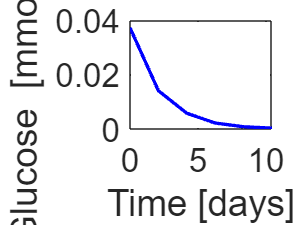

hold on

glucose_M16
%h=figure('Units','inches','Position',[0 0 1.25 0.9])
glucose(1:6)=0.0;
for t=1:6
    varname=genvarname(['media_' int2str((t-1)*1000)]);
    clear glucose_field;
    glucose_field=eval(varname);
    for x=1:352
        for y=1:352
            glucose(t)=glucose(t)+glucose_field(x,y);
        end
    end
end

plot(0.05*[0:1000:5000]/24,glucose(:),'LineWidth',2,'Color','red')
%xlim([0,7])
xlabel('Time [days]','FontSize',15)
ylabel('Glucose [mmol/cm^2]','FontSize',15)
%ylim([0 3.5e-3])
%xticklabels(gcf,'FontSize',10)
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 10.4167]
             YLim: [0 0.0400]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1957 0.1894 0.7093 0.7356]
            Units: 'normalized'

  Show all properties


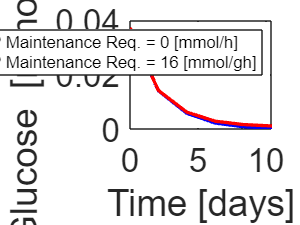

legend('ATP Maintenance Req. = 0 [mmol/h]','ATP Maintenance Req. = 16 [mmol/gh]','FontSize',10)
hold on

saveas(gcf,['glucose.png'])